%linear convolution
clc
clear all
close all
x=input('enter x: ')

x =      1     2     3     4


h=input('enter h: ')

h =      2     1     2     1


N=length(x)

N = 4

M=length(h)

M = 4

l=N+M-1

l = 7

y=zeros(1,l)

y =      0     0     0     0     0     0     0


for n=1:l
    y(n)=0
    for k=max(1,n-M+1):min(n,N)
        y(n)=y(n)+x(n-k+1)*h(k)
    end
end

y =      0     0     0     0     0     0     0


y =      2     0     0     0     0     0     0


y =      2     0     0     0     0     0     0


y =      2     4     0     0     0     0     0


y =      2     5     0     0     0     0     0


y =      2     5     0     0     0     0     0


y =      2     5     6     0     0     0     0


y =      2     5     8     0     0     0     0


y =      2     5    10     0     0     0     0


y =      2     5    10     0     0     0     0


y =      2     5    10     8     0     0     0


y =      2     5    10    11     0     0     0


y =      2     5    10    15     0     0     0


y =      2     5    10    16     0     0     0


y =      2     5    10    16     0     0     0


y =      2     5    10    16     4     0     0


y =      2     5    10    16    10     0     0


y =      2     5    10    16    12     0     0


y =      2     5    10    16    12     0     0


y =      2     5    10    16    12     8     0


y =      2     5    10    16    12    11     0


y =      2     5    10    16    12    11     0


y =      2     5    10    16    12    11     4


z=conv(x,h)

z =      2     5    10    16    12    11     4


lc=ifft(fft(x,l).*fft(h,l))

lc =     2.0000    5.0000   10.0000   16.0000   12.0000   11.0000    4.0000


clc
clear all
close all
x=input('enter x: ')

x =      1     2     3     4


N=length(x)

N = 4

h=input('enter h: ')

h =      2     1     2     1


M=length(h)

M = 4

l=max(N,M)

l = 4

x=[x zeros(l-N)]

x =      1     2     3     4


h=[h zeros(l-M)]

h =      2     1     2     1


y=zeros(1,l)

y =      0     0     0     0


for n=1:l
    y(n)=0
    for k=1:l
        id=mod(n-k,l)+1
        y(n)=y(n)+x(id)*h(k)
    end
end

y =      0     0     0     0


id = 1

y =      2     0     0     0


id = 4

y =      6     0     0     0


id = 3

y =     12     0     0     0


id = 2

y =     14     0     0     0


y =     14     0     0     0


id = 2

y =     14     4     0     0


id = 1

y =     14     5     0     0


id = 4

y =     14    13     0     0


id = 3

y =     14    16     0     0


y =     14    16     0     0


id = 3

y =     14    16     6     0


id = 2

y =     14    16     8     0


id = 1

y =     14    16    10     0


id = 4

y =     14    16    14     0


y =     14    16    14     0


id = 4

y =     14    16    14     8


id = 3

y =     14    16    14    11


id = 2

y =     14    16    14    15


id = 1

y =     14    16    14    16


z=cconv(x,h,l)

z =     14    16    14    16


cr=ifft(fft(x).*fft(h))

cr =     14    16    14    16


clc
clear all
close all
dtmf_fq=[
    941,1336;%0
    697,1209;%1
    697,1336;%2
    770,1209;%3
    770,1336;%4
    770,1477;%5
    852,1209;%6
    852,1336;%7
    852,1477;%8
    941,1336;%9
    ]

dtmf_fq =          941        1336
         697        1209
         697        1336
         770        1209
         770        1336
         770        1477
         852        1209
         852        1336
         852        1477
         941        1336


digit=input('enter digit (0-9): ')

digit = 2

fs = 44100

duration = 0.5000

t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


sgnl =          0    0.0991    0.1973    0.2935    0.3869    0.4764    0.5612    0.6405    0.7135    0.7794    0.8377    0.8877    0.9290    0.9611    0.9838    0.9967    0.9998    0.9931    0.9766    0.9505    0.9150    0.8705    0.8174    0.7562    0.6877    0.6123    0.5309    0.4443    0.3532    0.2588    0.1617    0.0631   -0.0362   -0.1351   -0.2326   -0.3279   -0.4200   -0.5079   -0.5908   -0.6679   -0.7384   -0.8016   -0.8569   -0.9038   -0.9418   -0.9705   -0.9896   -0.9990   -0.9985   -0.9882


sgnl2 =          0    0.1892    0.3716    0.5405    0.6899    0.8144    0.9095    0.9717    0.9988    0.9899    0.9452    0.8663    0.7562    0.6187    0.4589    0.2825    0.0959   -0.0942   -0.2808   -0.4574   -0.6173   -0.7550   -0.8655   -0.9446   -0.9896   -0.9989   -0.9721   -0.9102   -0.8154   -0.6912   -0.5419   -0.3732   -0.1909   -0.0017    0.1875    0.3700    0.5391    0.6887    0.8134    0.9088    0.9713    0.9988    0.9901    0.9457    0.8672    0.7573    0.6200    0.4604    0.2841    0.0976


sg =          0    0.2883    0.5689    0.8340    1.0768    1.2908    1.4707    1.6122    1.7123    1.7693    1.7829    1.7540    1.6851    1.5798    1.4426    1.2792    1.0957    0.8989    0.6958    0.4931    0.2976    0.1154   -0.0481   -0.1884   -0.3020   -0.3866   -0.4412   -0.4660   -0.4622   -0.4324   -0.3802   -0.3101   -0.2271   -0.1368   -0.0451    0.0421    0.1191    0.1808    0.2227    0.2409    0.2330    0.1972    0.1332    0.0419   -0.0746   -0.2132   -0.3696   -0.5386   -0.7144   -0.8906


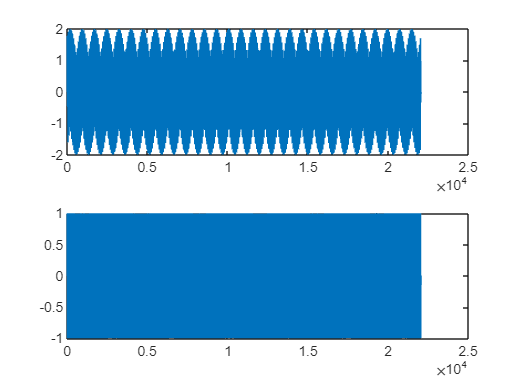

if digit>=0 &&digit<=9
    fs=44100
    duration=0.5
    t=0:1/fs:duration
    sgnl=sin(2*pi*dtmf_fq(digit+1,1)*t)
    sgnl2=sin(2*pi*dtmf_fq(digit+1,2)*t)
    sg=sgnl+sgnl2
    sound(sg,fs)
    subplot(2,1,1)
    plot(sg)
    subplot(2,1,2)
    plot(sgnl2)
else
    disp('enter b/w 0 and 9 ')
end

clc
clear all
close all
x=input('enter x: ')

x =      1     2     3     4


N=length(x)

N = 4

y=zeros(N,1)

y =      0
     0
     0
     0


for n=0:N-1
    for k=0:N-1
        y(n+1)=y(n+1)+x(k+1)*exp(-1*1i*2*pi*n*k/N)
    end
end

y =      1
     0
     0
     0


y =      3
     0
     0
     0


y =      6
     0
     0
     0


y =     10
     0
     0
     0


y =     10
     1
     0
     0


y =   10.0000 + 0.0000i
   1.0000 - 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 - 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   1.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -1.0000 - 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   2.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   1.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   1.0000 + 2.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
  -2.0000 + 2.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
  -2.0000 - 2.0000i


z=fft(x)

z =   10.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 + 0.0000i  -2.0000 - 2.0000i


clc
clear all
close all
x=input('enter x: ')

x =      1     2     3     4


N=length(x)

N = 4

y=zeros(1,N)

y =      0     0     0     0


for n=0:N-1
    for k=0:N-1
        y(n+1)=y(n+1)+x(k+1)*exp(1i*2*pi*n*k/N)
    end
    y(n+1)=y(n+1)/N
end

y =      1     0     0     0


y =      3     0     0     0


y =      6     0     0     0


y =     10     0     0     0


y =     2.5000         0         0         0


y =     2.5000    1.0000         0         0


y =    2.5000 + 0.0000i   1.0000 + 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -2.0000 + 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -2.0000 - 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i   1.0000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -1.0000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i   2.0000 - 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -2.0000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i   0.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i   1.0000 + 0.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i   1.0000 - 2.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i  -2.0000 - 2.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i  -2.0000 + 2.0000i


y =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i  -0.5000 + 0.5000i


z=ifft(x)

z =    2.5000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 + 0.0000i  -0.5000 + 0.5000i


clc
clear all
close all
x=input('enter x: ')

x =      1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     3     3     3     3     3     8    44     4     4     4     8     9     8     8    88     8     8     8     8     4


N=length(x)

N = 36

d=input('enter decimation_factor: ')

d = 2

i=1

i = 1

w=1

w = 1

if mod(N,d)==0
    l=N/d
else
    l=floor(N/d)
end

l = 18

y=zeros(1,l)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i=1:N
    if w<=N
        y(i)=x(w)
    end
    w=w+d
end

y =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


w = 3

y =      1     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


w = 5

y =      1     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


w = 7

y =      1     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0


w = 9

y =      1     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0


w = 11

y =      1     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0


w = 13

y =      1     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0


w = 15

y =      1     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0


w = 17

y =      1     2     2     2     2     2     2     2     3     0     0     0     0     0     0     0     0     0


w = 19

y =      1     2     2     2     2     2     2     2     3     3     0     0     0     0     0     0     0     0


w = 21

y =      1     2     2     2     2     2     2     2     3     3     3     0     0     0     0     0     0     0


w = 23

y =      1     2     2     2     2     2     2     2     3     3     3    44     0     0     0     0     0     0


w = 25

y =      1     2     2     2     2     2     2     2     3     3     3    44     4     0     0     0     0     0


w = 27

y =      1     2     2     2     2     2     2     2     3     3     3    44     4     8     0     0     0     0


w = 29

y =      1     2     2     2     2     2     2     2     3     3     3    44     4     8     8     0     0     0


w = 31

y =      1     2     2     2     2     2     2     2     3     3     3    44     4     8     8    88     0     0


w = 33

y =      1     2     2     2     2     2     2     2     3     3     3    44     4     8     8    88     8     0


w = 35

y =      1     2     2     2     2     2     2     2     3     3     3    44     4     8     8    88     8     8


w = 37

w = 39

w = 41

w = 43

w = 45

w = 47

w = 49

w = 51

w = 53

w = 55

w = 57

w = 59

w = 61

w = 63

w = 65

w = 67

w = 69

w = 71

w = 73

u=decimate(x,d)

u =     2.5261    1.3363    2.3679    2.0839    1.2742    3.1172    0.4796    3.6043    2.2469    1.4615   16.4359   16.9013    2.6622    4.6983   31.1064   33.1704    2.1356    4.0193


clc
clear all
close all
x=input('enter x ')

x =      1     2     3     4


I=input('enter intep_fact: ')

I = 2

N=length(x)

N = 4

l=N*I-1

l = 7

y=zeros(1,l)

y =      0     0     0     0     0     0     0


i=1

i = 1

w=1

w = 1

for i=1:l
    if w<=l
        y(w)=x(i)
    end
    w=w+I
end

y =      1     0     0     0     0     0     0


w = 3

y =      1     0     2     0     0     0     0


w = 5

y =      1     0     2     0     3     0     0


w = 7

y =      1     0     2     0     3     0     4


w = 9

w = 11

w = 13

w = 15